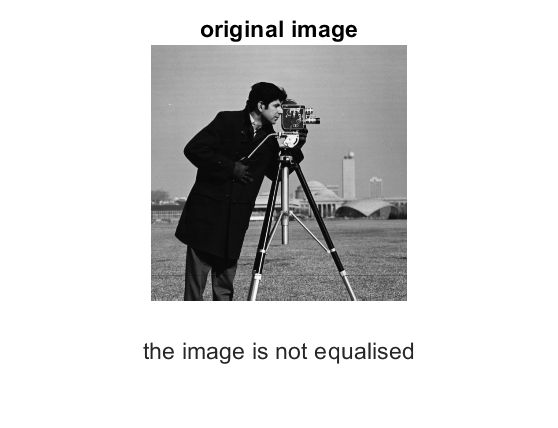

%read your image

Io=imread('input your image here***********');
%taking size of image
[x,y]=size(Io);
%calculating the occurrances of pixels in image 
H0=imhist(Io);
%taking discrete fourier transform counted occurances of image
X0=ft(H0',256);
%calculating value of delta
delta=0;
for c=2:129
    delta=delta+abs(X0(c))*exp(-(c-1));
end
    %findind zita value for input image

zita=(1-(delta/abs(X0(1))));

%comaparing zita with zita threshold for image of different size
imshow(Io)
title('original image')
%ouput
if(x==256&&y==256)
    if(zita>=0.8437)
       xlabel('the image already equalised')
    else
        xlabel('the image is not equalised')
    end
elseif(x==512&&y==384)
    if(zita>=0.8473)
        xlabel('the image already equalised')
    else
        xlable('the image is not equalised')
    end
 elseif(x==128&&y==128)
    if(zita>=0.8139)
        xlabel('the image already equalised')
    else
          xlabel('the image is not equalised')
    end
elseif(x==64&&y==64)
    if(zita>=0.8325)
          xlabel('the image already equlised')
    else
          xlabel('the image is not equalised')
    end
elseif(x==32&&y==32)
    if(zita>=0.8235)
          xlabel('the image already equlised')
    else
          xlabel('the image is not equalised')
    end
elseif(x==16&&y==16)
    if(zita>=0.8327)
          xlabel('the image already equlised')
    else
          xlabel('the image is not equalised')
    end
elseif(x==8&&y==8)
    if(zita>=0.8576)
          xlabel('the image already equlised')
    else
          xlabel('the image is not equalised')
    end
else
      xlabel('the size of this image is not appropriate as per algorithm')
end


%function for discrete fourier transform
function Xk=ft(xn,N)
         for n=0:1:N-1
             for k=0:1:N-1
                 p=exp(-2*pi*1j*n*k/N);
                 x2(k+1,n+1)=p;
             end
         end
         Xk=xn*x2;
end
 




